# Spherical Harmonics

Solution to Laplace equation in spherical coordinates.

## Complex spherical harmonics

The spherical harmonic of degree $n$ and order $m$ is defined as:


$$Y_n^m(\theta,\phi) \equiv (-1)^m \sqrt{\frac{2n+1}{4\pi}\frac{(n-m)!}{(n+m)!}}P_n^m(\cos(\theta))e^{im\phi}$$


where $P_n^m(x)$ is the associated Legendre function, unnormalized.

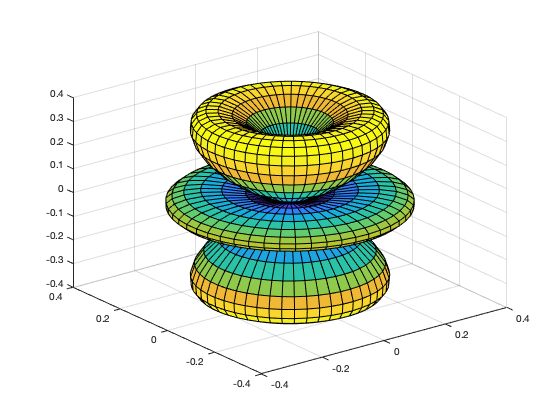

% create a 2D grid
th = linspace(0,pi,50);    % inclination
phi = linspace(0,2*pi,50); % azimuth
[th,phi] = meshgrid(th,phi);

% compute spherical harmonic of degree 3 and order 1
Y = harmonicY(3,1,th,phi);

% plot the magnitude
[x,y,z] = sph2cart(phi,pi/2-th,abs(Y));
surf(x,y,z,abs(Y));

## Real spherical harmonics

Real spherical harmonics can be calculated by setting the property `'type'` to `'real'`.

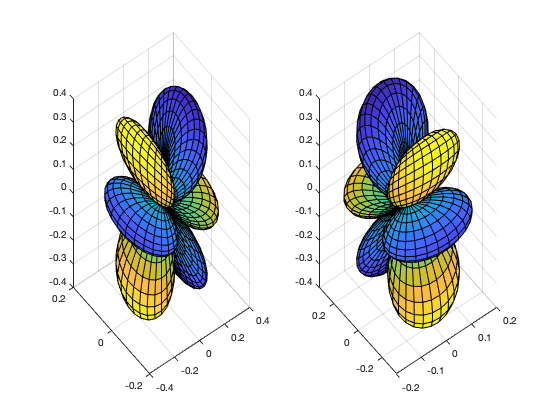

% compute real spherical harmonic of degree 3 and order 1, -1.
Yc = harmonicY(3,1,th,phi,'type','real');
Ys = harmonicY(3,-1,th,phi,'type','real');

% plot
[x,y,z] = sph2cart(phi,pi/2-th,abs(Yc));
subplot(121); surf(x,y,z,Yc);
[x,y,z] = sph2cart(phi,pi/2-th,abs(Ys));
subplot(122); surf(x,y,z,Ys);

## Surface and solid spherical harmonics

Spherical harmonics as defined above are also called *surface* spherical harmonics because they are a function of two angles evaluated over the surface of a sphere.

A surface spherical harmonic of degree $n$ multiplied by $r^n$ is called a *solid* spherical harmonic. If a radius $r$ is specified as a 5th argument, a solid spherical harmonic is computed. Otherwise, a surface spherical harmonic is computed.

n = 2; m = 0; th = 1; phi = 1; r = 2;
harmonicY(n,m,th,phi) * r^n % surface harmonic multiplied by r^n

ans = -0.1567

harmonicY(n,m,th,phi,r)     % solid harmonic

ans = -0.1567

## Normalization

Spherical harmonics are orthogonal functions. However, they can additionally be made orthonormal by choosing an appropriate normalization factor:


$$\sqrt{\frac{2n+1}{4\pi}\frac{(n-m)!}{(n+m)!}}$$


This factor is included by default but can be excluded from the computation using the property `'norm'`.

n = 1; m = 0; th = 0; phi = 0;
harmonicY(n,m,th,phi)              % normalized

ans = 0.4886

harmonicY(n,m,th,phi,'norm',false) % unnormalized

ans = 1

## Condon-Shortley phase

The term $(-1)^m$ in the definition above is known as the Condon-Shortley phase. This term is not strictly necessary in the definition of spherical harmonics but is useful in the quantum theory of angular momentum.

This term is included by default but can be excluded from the computation using the property `'phase'`.

n = 2; m = 1; th = 1; phi = 1; r = 2;
harmonicY(n,m,th,phi)               % with phase term

ans = -0.1898 - 0.2956i

harmonicY(n,m,th,phi,'phase',false) % without phase term

ans = 0.1898 + 0.2956i

## References

Whittaker, E. T., and G. N. Watson. “The Equations of Mathematical Physics.” A Course of Modern Analysis, Cambridge University Press, pp. 386–403, doi:10.1017/cbo9780511608759.019.

Arfken, George B., et al. “Legendre Functions.” Mathematical Methods for Physicists, Elsevier, 2013, pp. 715–772, doi:10.1016/b978-0-12-384654-9.00015-3.